Tot = 7.8000e+09;
% comparing R0
consts_R0 = [6/10, 6/10, 6/10, 5/10, 4/10, 3/10, 2/10, 2/10;
          1/10, 1.5/10, 2/10, 2/10, 2/10, 2/10, 1.5/10, 2/10;
          .1/10, .1/10, .1/10. .1/10, .1/10, .1/10, .1/10, .1/10;
          .5/10, .5/10, .5/10, .5/10, .5/10, .5/10, .5/10, .5/10;];
% 1% reinfection rate
% 5% mortality in US indicated by Johns Hopkins https://coronavirus.jhu.edu/data/mortality

consts_resusceptible = [6/10, 6/10, 6/10, 6/10, 6/10, 6/10, 6/10;
          2/10, 2/10, 2/10, 2/10, 2/10, 2/10, 2/10;
          .1/10. .5/10, 1/10, 2/10, 4/10, 8/10, 10/10;
          .5/10, .5/10, .5/10, .5/10, .5/10, .5/10, .5/10;];

% Experimenting with constants
% I0 = 1000000; S0 = Tot-I0;
% pretty almost oscilations
% [t,rw] = ode45(@(t,y) SIRSD(t, y, 6/10, 3/10, .5/10, 0), [0 200], [S0, I0, 0, 0]);
% [t,rw] = ode45(@(t,y) SIRSD(t, y, 4/10, 2/10, .3/10, 0), [0 200], [S0, I0, 0, 0]);
%[t,rw] = ode45(@(t,y) SIRSD(t, y, 4/10, 2/10, .3/10, 0), [0 200], [S0, I0, 0, 0]);
%[t,rw] = ode45(@(t,y) SIRSD(t, y, 4/10, 2/10, .1/10, .05), [0 2000], [S0, I0, R0, 0]/Tot);
%figure; plotIt(t,rw, Tot, "SIRS Model")


## Altering Io

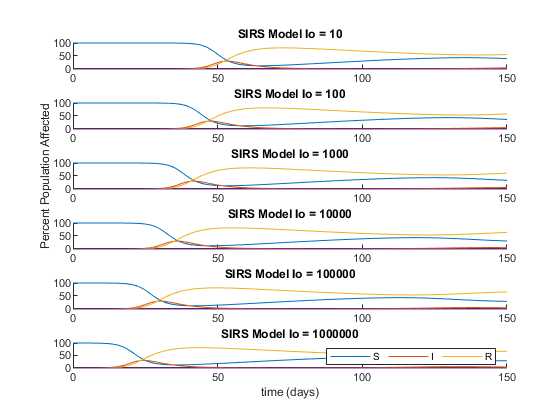

figure()
for (i=1:6)
    I0 = 1*10^i; S0 = Tot-I0;    
    [t,rw] = ode45(@(t,y) SIRSD(t, y, 6/10, 2/10, .1/10, 0), [0 150], [S0, I0, 0, 0]);
    subplot(6,1,i); plotIt(t, rw, Tot, "SIRS Model Io = "+string(I0));
end
subplot(6,1,3); ylabel("Percent Population Affected")
subplot(6,1,6);legend('S', 'I', 'R', 'Orientation', 'horizontal')
xlabel('time (days)')

## SIRSD Model

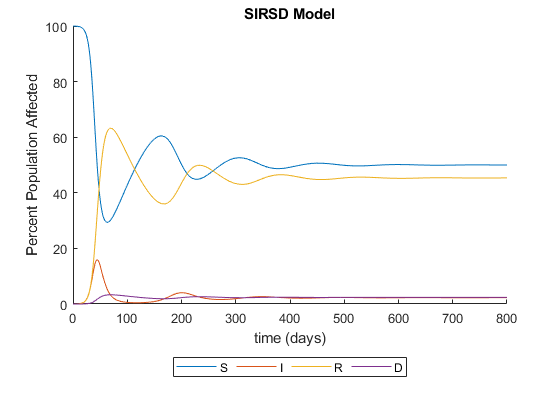

I0 = 1000000; S0 = Tot-I0;
[t,rw] = ode45(@(t,y) SIRSD(t, y, 4/10, 2/10, .1/10, .05), [0 800], [S0, I0, 0, 0]);
figure; plotIt(t, rw, Tot, "SIRSD Model");
ylabel("Percent Population Affected"); xlabel('time (days)')
legend('S', 'I', 'R', 'D', 'Orientation', 'horizontal', 'Location', 'southoutside')

## Altering Ro

Infection Rate: 0.60, Recovery Rate: 0.10, Resucceptible Rate: 0.01, Death Rate: 0.05

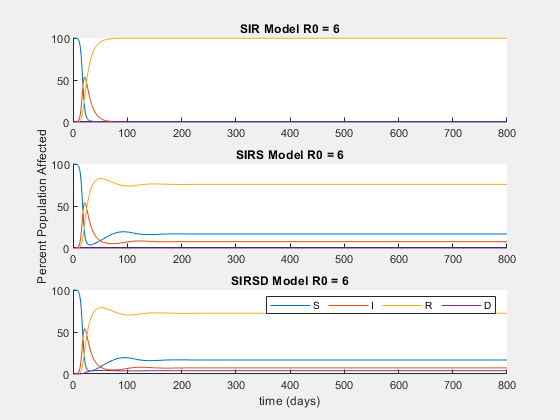

Infection Rate: 0.60, Recovery Rate: 0.15, Resucceptible Rate: 0.01, Death Rate: 0.05

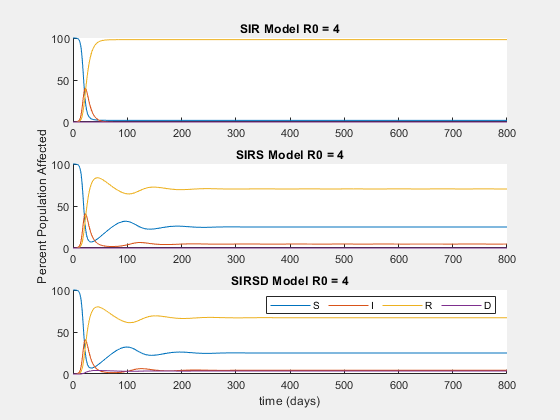

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

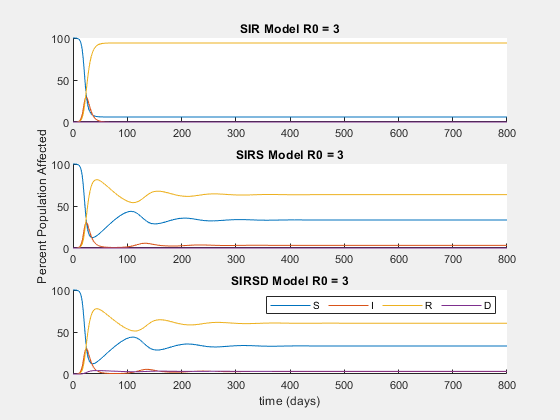

Infection Rate: 0.50, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

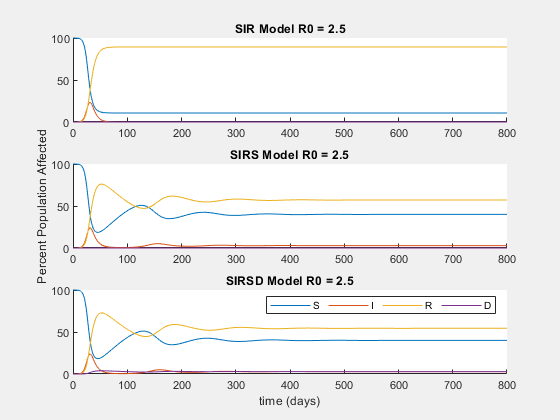

Infection Rate: 0.40, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

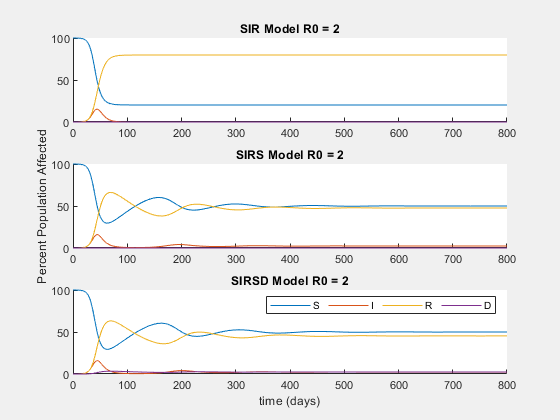

Infection Rate: 0.30, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

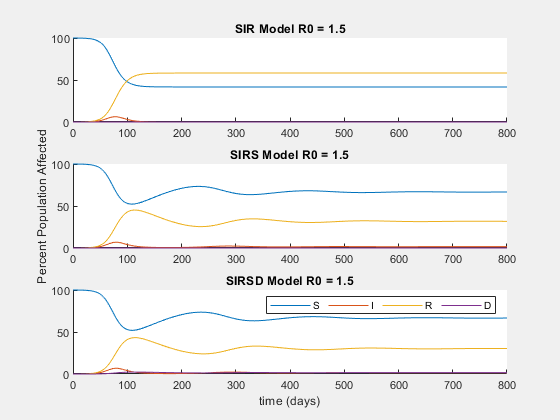

Infection Rate: 0.20, Recovery Rate: 0.15, Resucceptible Rate: 0.01, Death Rate: 0.05

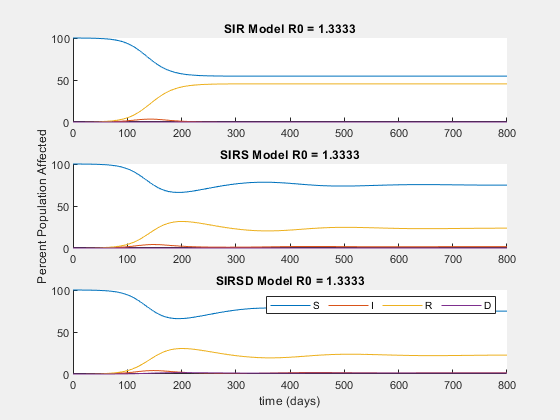

Infection Rate: 0.20, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

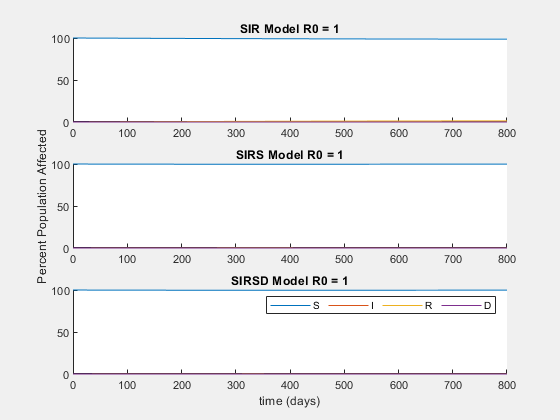

consts = consts_R0;
I0 = 1*10^6; S0 = Tot-I0;
for (i=1:length(consts(1,:)))
    figure()
    run3Models(S0, I0, Tot, consts(:,i)', 800, " R0 = "+string(consts(1,i)/consts(2,i)))
    subplot(3,1,3); xlabel('time (days)')
    legend("S", "I", "R", "D", 'Orientation', 'horizontal')
    
end

## Altering Re-Susceptibility Rate

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

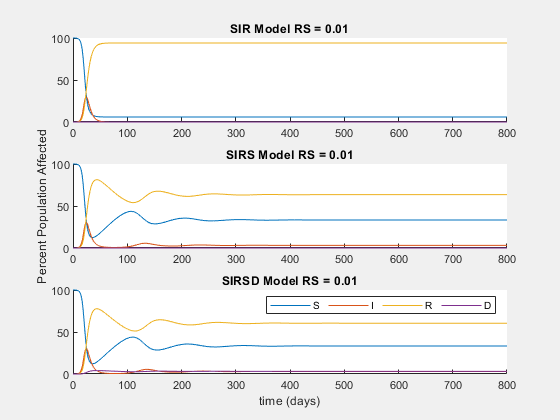

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.05, Death Rate: 0.05

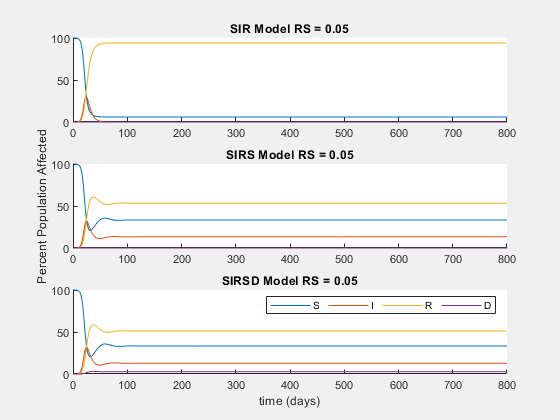

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.10, Death Rate: 0.05

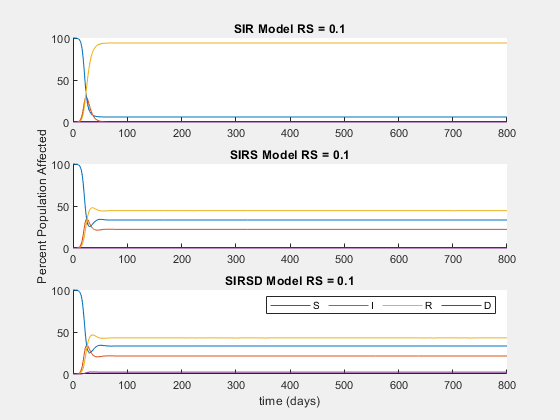

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.20, Death Rate: 0.05

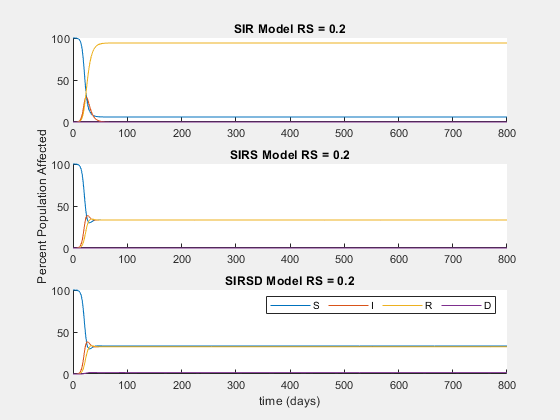

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.40, Death Rate: 0.05

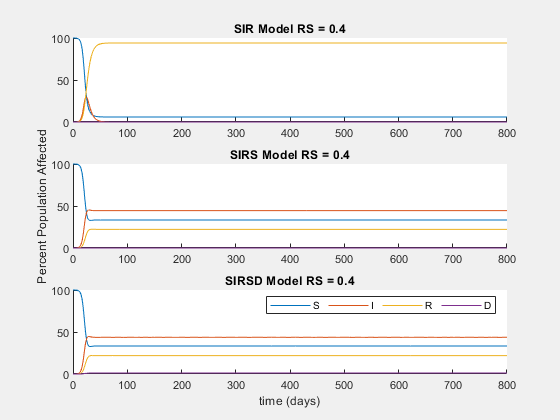

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.80, Death Rate: 0.05

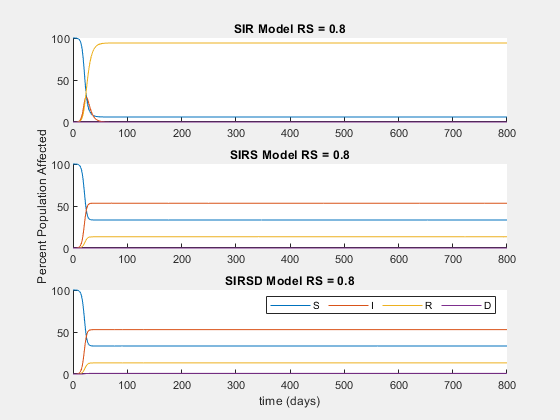

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 1.00, Death Rate: 0.05

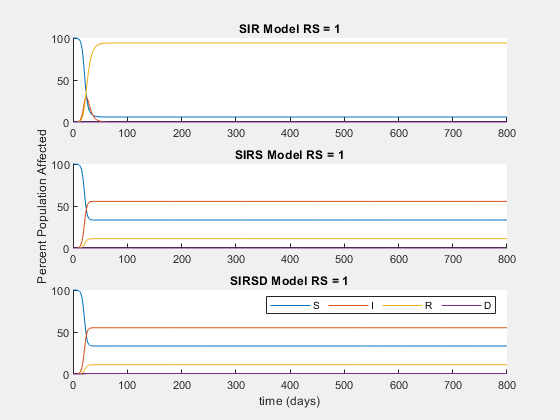

consts = consts_resusceptible;
I0 = 1*10^6; S0 = Tot-I0;
for (i=1:length(consts(1,:)))
    figure()
    run3Models(S0, I0, Tot, consts(:,i)', 800, " RS = "+string(consts(3,i)))
    subplot(3,1,3); xlabel('time (days)')
    legend("S", "I", "R", "D", 'Orientation', 'horizontal')
    
end

## Altering Population Size

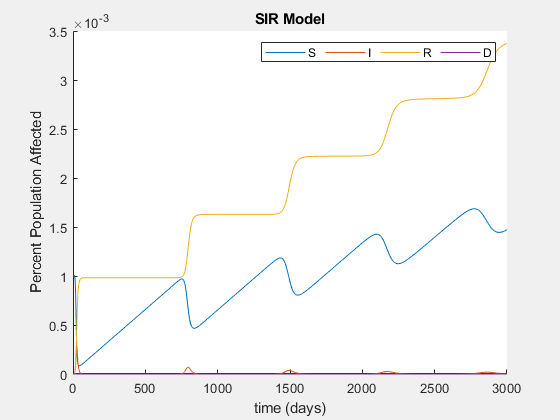

I0 = 10; S0 = 78000-I0;
consts = [6/10; 2/10; .1/10; .5/10];
[t,rw] = ode45(@(t,y) SIRSDpop(t, y, consts(1), consts(2), 0, 0), [0 3000], [S0, I0, 0, 0]);
figure(); plotIt(t, rw, Tot, "SIR Model")
ylabel("Percent Population Affected"); xlabel('time (days)');
legend("S", "I", "R", "D", 'Orientation', 'horizontal')


Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

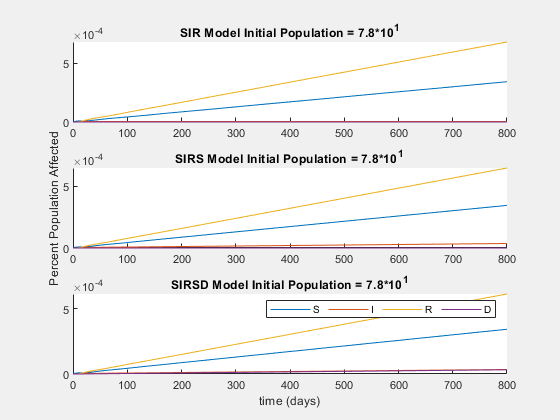

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

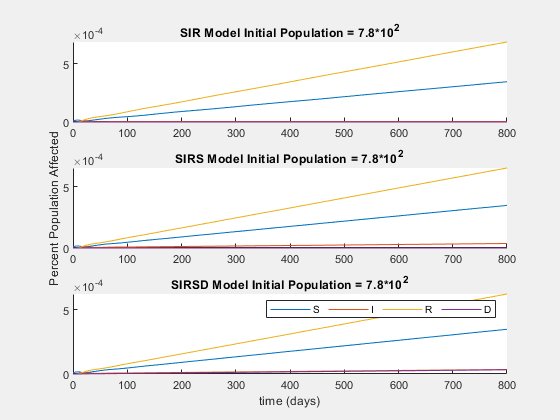

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

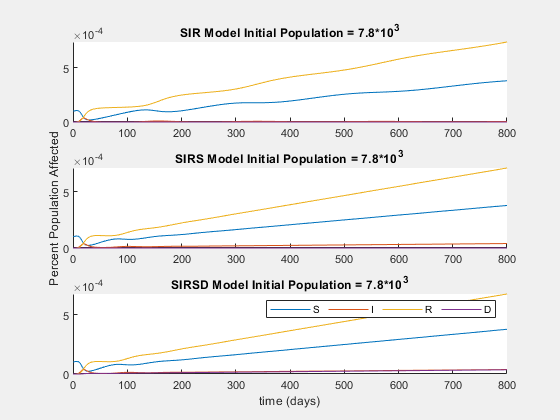

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

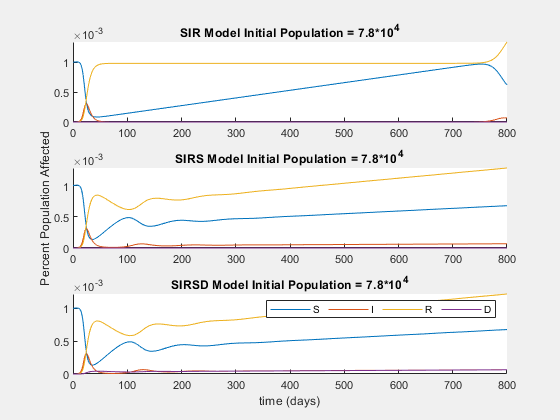

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

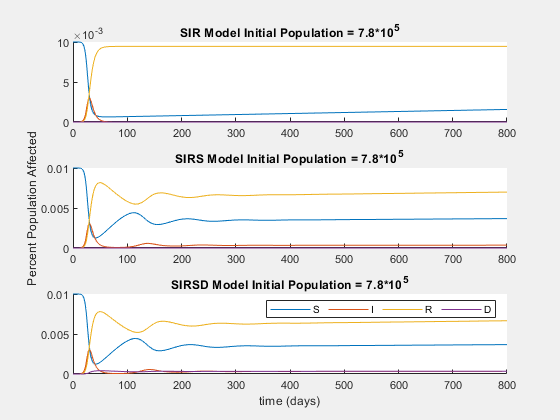

Infection Rate: 0.60, Recovery Rate: 0.20, Resucceptible Rate: 0.01, Death Rate: 0.05

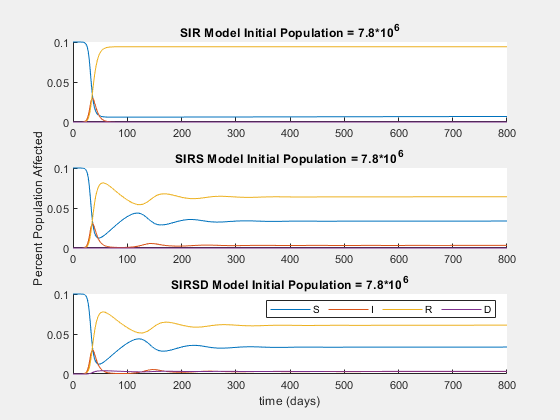


I0 = 10; S0_array = 7.8*10.^([1:6])-I0;
% consts = [6/10; 2/10; .1/10; .5/10];
for (i=1:length(S0_array))
    S0 = S0_array(i);
    figure()
    run3ModelsPop(S0, I0, Tot, consts', 800, " Initial Population = 7.8*10^"+string(i))
    subplot(3,1,3); xlabel('time (days)')
    legend("S", "I", "R", "D", 'Orientation', 'horizontal')
    
end

## Total Impact - Initial Population

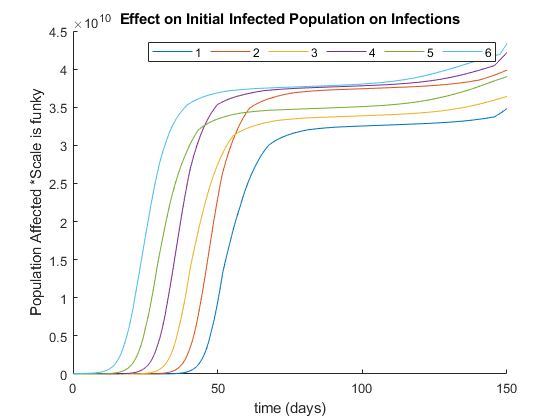

figure()
for (i=1:6)
    I0 = 1*10^i; S0 = Tot-I0;    
    [t,rw] = ode45(@(t,y) SIRSD(t, y, 6/10, 2/10, .1/10, .5/10), [0 150], [S0, I0, 0, 0]);
    plotIndivTotalTrend(t, rw(:,2));
end
ylabel("Population Affected *Scale is funky")
xlabel('time (days)')
legend(string([1:6]), 'Orientation', 'horizontal')
title("Effect on Initial Infected Population on Infections")

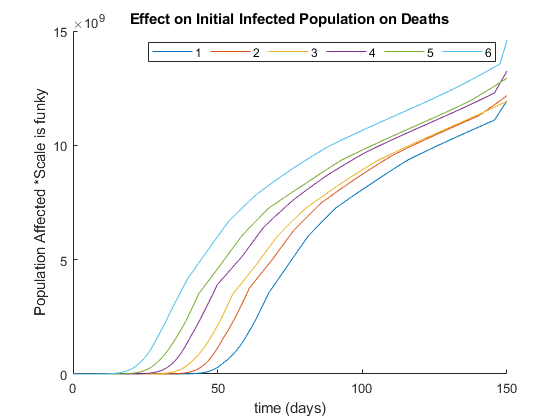


figure()
for (i=1:6)
    I0 = 1*10^i; S0 = Tot-I0;    
    [t,rw] = ode45(@(t,y) SIRSD(t, y, 6/10, 2/10, .1/10, .5/10), [0 150], [S0, I0, 0, 0]);
    plotIndivTotalTrend(t, rw(:,4));
end
ylabel("Population Affected *Scale is funky")
xlabel('time (days)')
legend(string([1:6]), 'Orientation', 'horizontal')
title("Effect on Initial Infected Population on Deaths")

## Total Impact - Ro Population

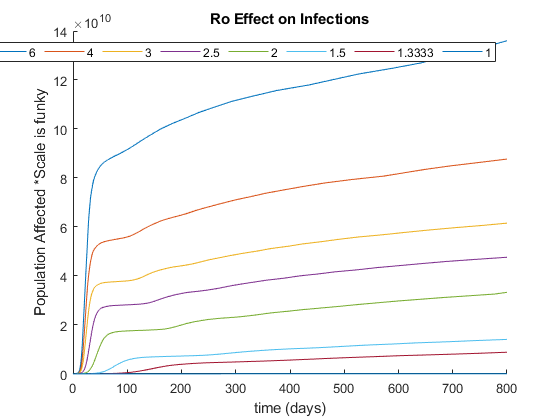

figure()
for (i=1:length(consts_R0(1,:)))
    consts = consts_R0(:,i);
    [t,rw] = ode45(@(t,y) SIRSDpop(t, y, consts(1), consts(2), consts(3), consts(4)), [0 800], [S0, I0, 0, 0]);
    plotIndivTotalTrend(t, rw(:,2));
end
ylabel("Population Affected *Scale is funky")
xlabel('time (days)')
legend(string([consts_R0(1,:)./consts_R0(2,:)]), 'Orientation', 'horizontal')
title("Ro Effect on Infections")

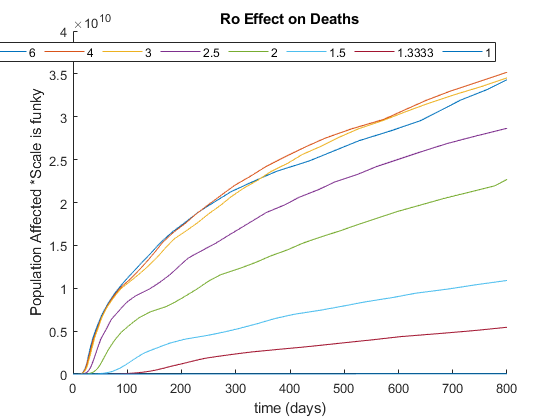


figure()
for (i=1:length(consts_R0(1,:)))
    consts = consts_R0(:,i);
    [t,rw] = ode45(@(t,y) SIRSDpop(t, y, consts(1), consts(2), consts(3), consts(4)), [0 800], [S0, I0, 0, 0]);
    plotIndivTotalTrend(t, rw(:,4));
end
ylabel("Population Affected *Scale is funky")
xlabel('time (days)')
legend(string([consts_R0(1,:)./consts_R0(2,:)]), 'Orientation', 'horizontal')
title("Ro Effect on Deaths")

## Functions

function plotIndivTotalTrend(t, rw)
    sumrw = zeros(size(rw));
    for (i=1:length(rw))
        sumrw(i) = sum(rw(1:i));
    end
    hold on
    plot(t,sumrw(:,:))
    % plot(t, rw) % plot against individual timepoints
    hold off
end

function plotTotalTrend(t, rw)
    sumrw = zeros(size(rw));
    for (i=1:length(rw))
        for (j=1:4) % for each line 1:4, or just track deaths and infections [2,4]
            sumrw(i,j) = sum(rw(1:i,j));
        end
    end
    hold on
    plot(t,sumrw(:,:))
    % plot(t, rw) % plot against individual timepoints
    hold off
end

function run3Models(S0, I0, Tot, consts, timelim, extraname)
    fprintf("Infection Rate: %.2f, Recovery Rate: %.2f, Resucceptible Rate: %.2f, Death Rate: %.2f", [consts(1), consts(2), consts(3), consts(4)])
    R0 = consts(1)/consts(2);
    [t,rw] = ode45(@(t,y) SIRSD(t, y, consts(1), consts(2), 0, 0), [0 timelim], [S0, I0, 0, 0]);
    subplot(3,1,1); plotIt(t, rw, Tot, ("SIR Model" + extraname))
    [t,rw] = ode45(@(t,y) SIRSD(t, y, consts(1), consts(2), consts(3), 0), [0 timelim], [S0, I0, 0, 0]);
    subplot(3,1,2); plotIt(t, rw, Tot, ("SIRS Model" + extraname))
    [t,rw] = ode45(@(t,y) SIRSD(t, y, consts(1), consts(2), consts(3), consts(4)), [0 timelim], [S0, I0, 0, 0]);
    subplot(3,1,3); plotIt(t, rw, Tot, ("SIRSD Model" + extraname))
    subplot(3,1,2); ylabel("Percent Population Affected")

    
end    

function run3ModelsPop(S0, I0, Tot, consts, timelim, extraname)
    fprintf("Infection Rate: %.2f, Recovery Rate: %.2f, Resucceptible Rate: %.2f, Death Rate: %.2f", [consts(1), consts(2), consts(3), consts(4)])
    R0 = consts(1)/consts(2);
    [t,rw] = ode45(@(t,y) SIRSDpop(t, y, consts(1), consts(2), 0, 0), [0 timelim], [S0, I0, 0, 0]);
    if (Tot==0) Tot = sum(rw, 2); end
    subplot(3,1,1); plotIt(t, rw, Tot, ("SIR Model" + extraname))
    [t,rw] = ode45(@(t,y) SIRSDpop(t, y, consts(1), consts(2), consts(3), 0), [0 timelim], [S0, I0, 0, 0]);
    if (Tot==0) Tot = sum(rw, 2); end
    subplot(3,1,2); plotIt(t, rw, Tot, ("SIRS Model" + extraname))
    [t,rw] = ode45(@(t,y) SIRSDpop(t, y, consts(1), consts(2), consts(3), consts(4)), [0 timelim], [S0, I0, 0, 0]);
    if (Tot==0) Tot = sum(rw, 2); end
    subplot(3,1,3); plotIt(t, rw, Tot, ("SIRSD Model" + extraname))
    subplot(3,1,2); ylabel("Percent Population Affected")
    subplot(3,1,3);legend('S', 'I', 'R', 'D', 'Orientation', 'horizontal')
    xlabel('time (days)')
    
end 

function plotIt(t, rw, Tot, name)
    hold on
    plot(t, rw(:,:)./Tot.*100, "-");
    %legend('S', 'I', 'R', 'D')
    %xlabel('time (days)')
    %ylabel('Precent Population Affected')
    title(name)
    hold off
end


function dx = SIRSD(t, sys, beta, gamma, zeta, deathrate)
    dx = zeros(4,1); % derivative vector
    S = sys(1); I=sys(2); R = sys(3); N = S+I+R+sys(4);
    dx(1) = -(beta*S*I)/N + zeta*R;
    dx(2) = (beta*S*I)/N - gamma*I;
    Recovered = gamma*I - zeta*R;
    %deathrate = deathrate*(I/N); % can we make deathrate more dynamic based on how much of population is sick (i.e. hospital overflow)?
    dx(3) = Recovered*(1-deathrate); % alive
    dx(4) = Recovered*deathrate; % dead
end


function dx = SIRSDpop(t, sys, beta, gamma, zeta, deathrate)
    dx = zeros(3,1); % derivative vector
    S = sys(1); I=sys(2); R = sys(3); N = S+I+R+sys(4);
    dx(1) = -(beta*S*I)/N + zeta*R + 100; % 100 people per day
    %dx(1) = -(beta*S*I)/N + zeta*R + 10*I/N; % trying to make a better population increase curve - function of how many infected people there are
    %dx(1) = -(beta*S*I)/N + zeta*R + ((7.9*10^9-(N))/(7.9*10^9)); % trying to make a better population increase curve based on how many people are still in the world to be exposed
    %(i.e. the total population that is factored in so far, emulating country-style expansion)
    dx(2) = (beta*S*I)/N - gamma*I;
    Recovered = gamma*I - zeta*R;
    dx(3) = Recovered*(1-deathrate); % alive
    dx(4) = Recovered*deathrate; % dead
end